# Testing real scanned-OCT data

At first read the data

D1 = fopen('C:\MatkivskiyV\science\article8\ab_comp_matlab\data\data_from_setup\USAF_4.dat');
A = fread(D1,1024*256*256*2,'single');
fclose(D1);

Obtains complex data from single. There is a strange tilted component of the image (there may be a reflected component). 

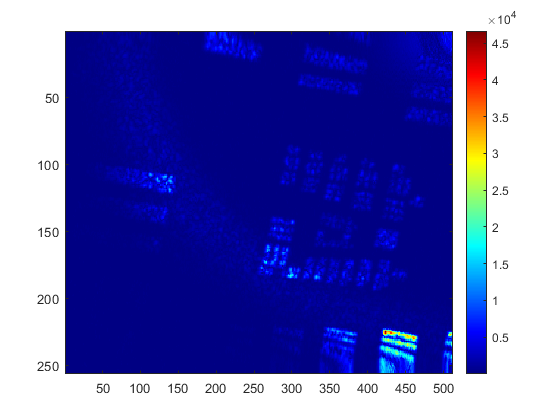

B = A(1:2:end) + 1j*A(2:2:end);
C = reshape(B,[256,256,1024]);
E0 = squeeze(sum(C(:,105,1:2:end),2));
figure(); imagesc(abs(E0)); colorbar ; colormap(jet);

Cut only usaf component

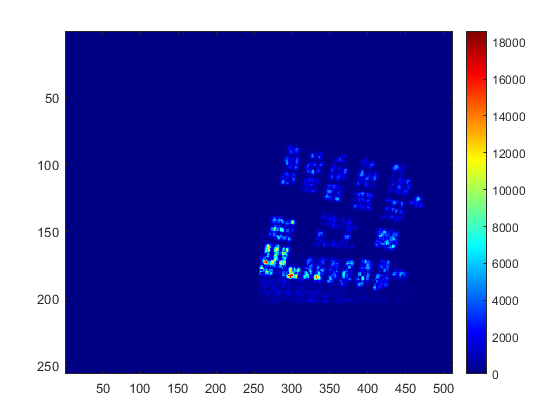

E = zeros(size(E0),'single');
E(73:203,257:472) = E0(73:203,257:472);
figure(); imagesc(abs(E)); colorbar ; colormap(jet);

The Fourier spectr is found. It's not bed enought, but the spectrum is shifted.

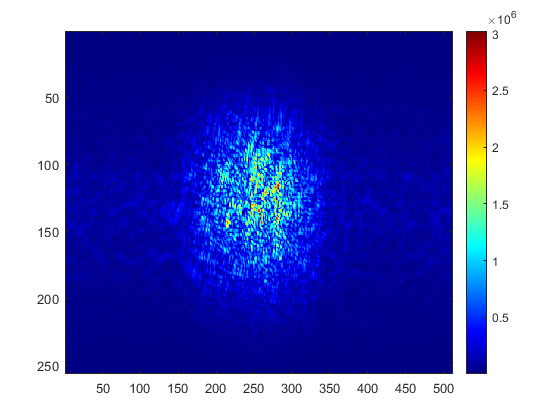

fE = FTS(E);
fE  = circshift(fE,[135 -20]);
figure(); imagesc(abs(fE)); colorbar ; colormap(jet);

Read the aberrated data

D1 = fopen('C:\MatkivskiyV\science\article8\ab_comp_matlab\data\data_from_setup\USAF_4_ab_2.dat');
D = zeros(1024,256,256,'single');
A = fread(D1,1024*256*256*2,'single');
fclose(D1);

B = A(1:2:end) + 1j*A(2:2:end);
C = reshape(B,[256,256,1024]);

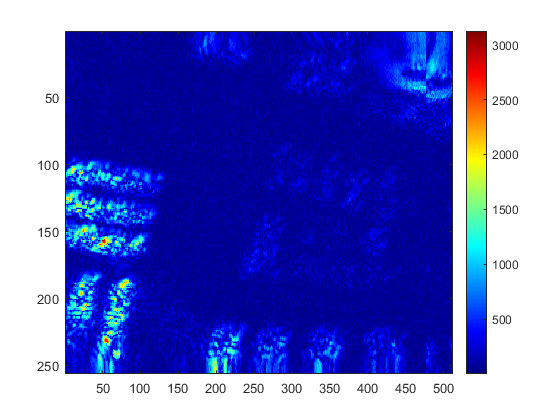

E0a = squeeze(sum(C(:,108:112,1:2:end),2));
figure(); imagesc(abs(E0a)); colorbar ; colormap(jet);

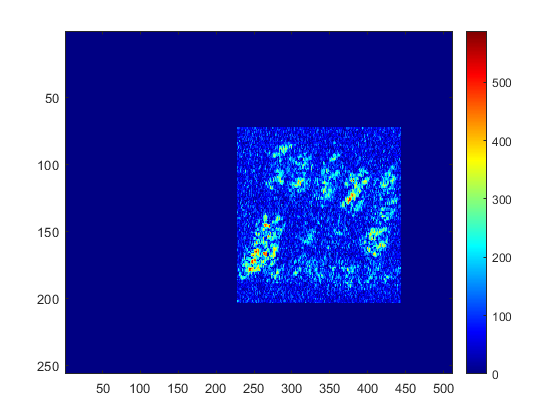

Ea = zeros(size(E0a),'single');
Ea(73:203,228:444) = E0a(73:203,228:444);
figure(); imagesc(abs(Ea)); colorbar ; colormap(jet);

Obtaing a spectrum for the aberrated data and compairing it to non-aberrated spectrum.

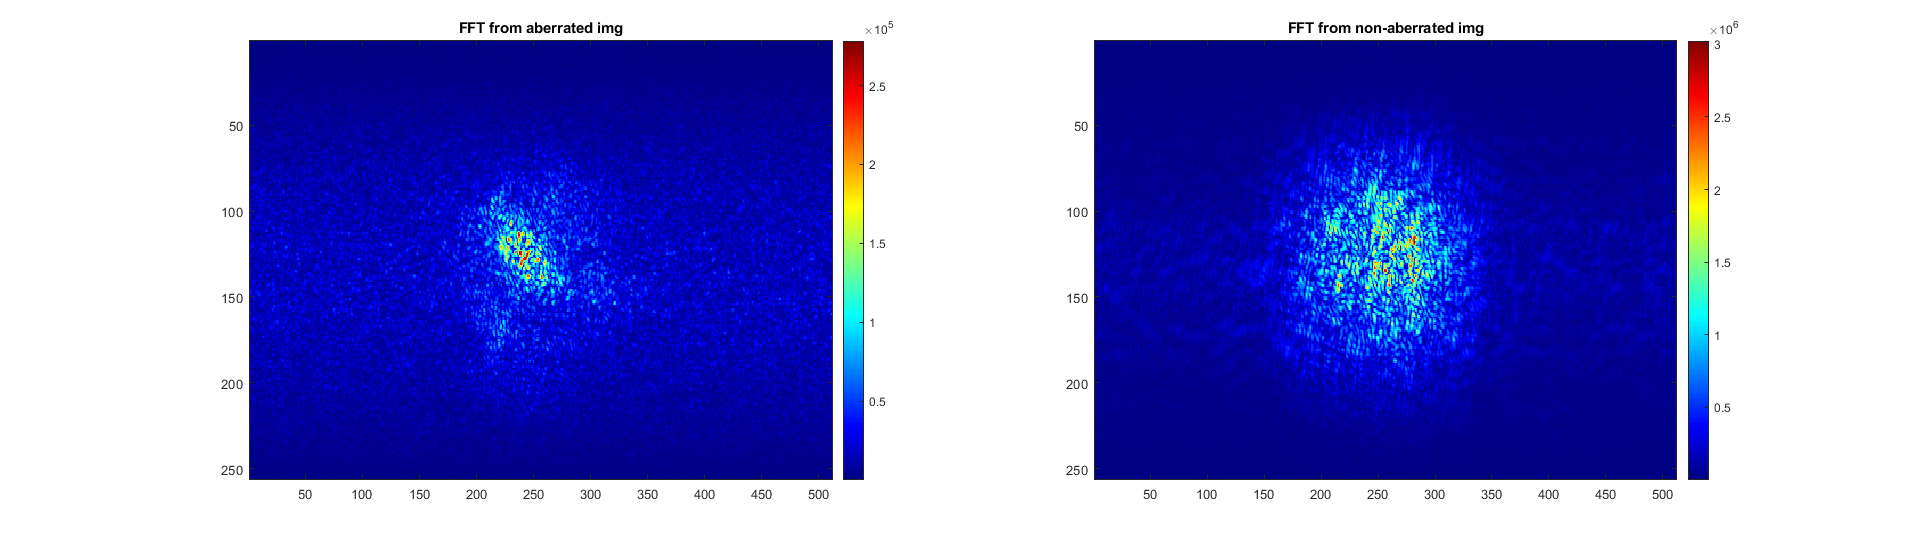

fEa = FTS(Ea);
fEa  = circshift(fEa,[135 -20]);
f = figure(); 
subplot(1,2,1);
imagesc(abs(fEa)); colorbar ; colormap(jet);
title('FFT from aberrated img');
subplot(1,2,2);
imagesc(abs(fE)); colorbar ; colormap(jet);
title('FFT from non-aberrated img');
set(f,'Units','normalized','position',[0 0 1 .5] )

Circ filtration 

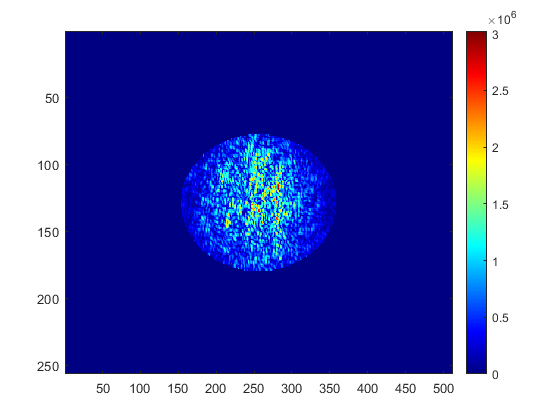

N = 256;
dxt = 1/N;

[xt,yt] = meshgrid(-0.5:dxt/2:0.5-dxt/2,-0.5:dxt:0.5-dxt);
xt = xt + dxt/2 ; % Это нужно, чтобы отцентрировать is_in_circle
yt = yt + dxt/4;
rt = sqrt(xt.^2 + yt.^2);

imagesc(abs(fE).*circ(rt*5)); colorbar ; colormap(jet);

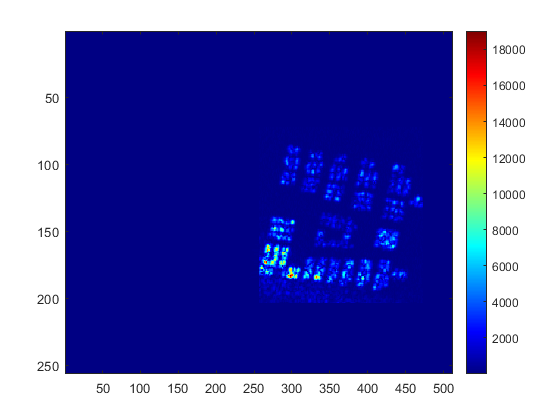

imagesc(abs(iFTS(fE.*circ(rt*2)))); colorbar ; colormap(jet);